### Problema 1

clear all

syms Kc s a

% Valores del ejercicio
G_s = 10/(s*(s+1));
Gc_s = (Kc*(s+a))/s;
Gop_s = G_s*Gc_s

$$Gop\_s = \frac{10\,\mathrm{Kc}\,\left(a+s\right)}{s^{2}\,\left(s+1\right)}$$

Wn = sqrt(10)

Wn =        3.1623


dampping = .5/sqrt(10)

dampping =       0.15811



[N_Gop_s, D_Gop_s] = numden(Gop_s);
poles_r = solve(D_Gop_s == 0, s);
poles_r = double(poles_r)

poles_r =     -1
     0
     0



figure
plot(real(poles_r), imag(poles_r), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)


% Encontramos polinómio deseado
Pd_s = s^2 + (2*dampping*Wn*s) + Wn^2;
% Ver númericamente
var = vpa(Pd_s)

$$var = s^{2}+s+10.0$$


poles_d = vpa(solve(Pd_s == 0, s))

$$poles\_d = \left(\begin{array}{c} -0.5-3.1224989991991991029234465604699\,\mathrm{i}\\ -0.5+3.1224989991991991029234465604699\,\mathrm{i} \end{array}\right)$$

poles_d = double(poles_d)

poles_d =          -0.5 -     3.1225i
         -0.5 +     3.1225i


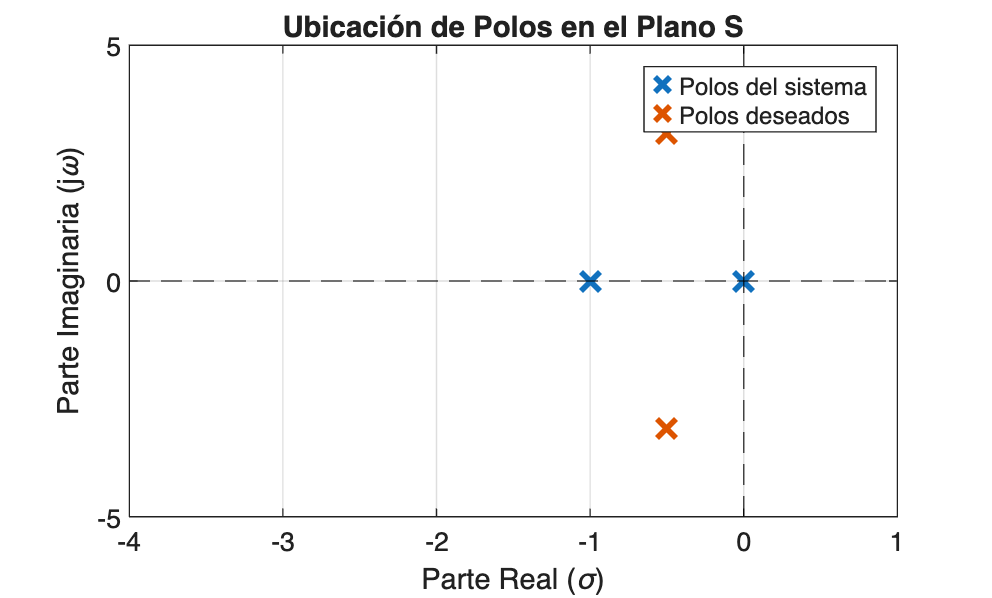



% Ver polos del sistema y polos que 
% buscamos ser dominantes

hold on
plot(real(poles_d), imag(poles_d), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)

xlim([-4 1])
ylim([-5 5])


grid on
xline(0, '--k') % Eje imaginario
yline(0, '--k') % Eje real
xlabel('Parte Real (\sigma)')
ylabel('Parte Imaginaria (j\omega)')
title('Ubicación de Polos en el Plano S')
legend('Polos del sistema', 'Polos deseados')
hold off


% Encontrar angulos de cada polo

% Calculamos el ángulo de cada polo respecto a sd
sd = poles_d(1);

angles = arrayfun(@(p) rad2deg(abs(angle(sd-p))), poles_r)

angles =        80.903
       99.097
       99.097


angle_sum = sum(angles)

angle_sum =         279.1



syms phi

phi_angle = solve(angle_sum-phi == 180, phi)

$$phi\_angle = \frac{108958783351027}{1099511627776}$$

vpa (phi_angle)

$$ans = 99.097436169383399828802794218063$$

x_val = abs(imag(sd))/tand(180-phi_angle)

$$x\_val = \frac{\sqrt{39}}{2\,\tan\left(\frac{88953309648653\,\pi }{197912092999680}\right)}$$


% Encontramos la alpha (cero) del sistema
alpha = -(real(sd)-x_val);
vpa(alpha)

$$ans = 1.0000000000000006465244761816671$$


% Usamos la condicón de magnitud para encontrar la ganancia
Gop_s_wKc = Gop_s/Kc

$$Gop\_s\_wKc = \frac{10\,\left(a+s\right)}{s^{2}\,\left(s+1\right)}$$

Kc_den = subs(Gop_s_wKc, [a, s], [alpha, sd])

$$Kc\_den = -\frac{10\,\left(\frac{\sqrt{39}}{2\,\tan\left(\frac{88953309648653\,\pi }{197912092999680}\right)}-\frac{\sqrt{39}\,\mathrm{i}}{2}\right)}{\left(-\frac{1}{2}+\frac{\sqrt{39}\,\mathrm{i}}{2}\right)\,{\left(\frac{1}{2}+\frac{\sqrt{39}\,\mathrm{i}}{2}\right)}^{2}}$$

Kc = 1/abs(Kc_den)

$$Kc = \frac{\sqrt{10}}{\sqrt{\frac{39}{4\,{\tan\left(\frac{88953309648653\,\pi }{197912092999680}\right)}^{2}}+\frac{39}{4}}}$$

Kc = vpa(Kc);

Kp = Kc

$$Kp = 0.99999999999999996767377619091663$$

Ki = vpa(Kc*alpha)

$$Ki = 1.0000000000000006141982523725837$$


%simunlink_PID_creator('GEN__S3_1_PI', sym2tf(G_s), 1, 1, 1, 0)

### Problema 2

clear all

syms Kc s b

% Valores del ejercicio
G_s = 1/(10000*(s^2 - 1.772));
Gc_s = (Kc*(s+b));
Gop_s = G_s*Gc_s

$$Gop\_s = \frac{\mathrm{Kc}\,\left(b+s\right)}{10000\,s^{2}-17720}$$

Wn = 0.5

Wn =           0.5


dampping = 0.7

dampping =           0.7



[N_Gop_s, D_Gop_s] = numden(Gop_s);
poles_r = solve(D_Gop_s == 0, s);
poles_r = double(poles_r)

poles_r =       -1.3312
       1.3312



figure
plot(real(poles_r), imag(poles_r), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)


% Encontramos polinómio deseado
Pd_s = s^2 + (2*dampping*Wn*s) + Wn^2;
% Ver númericamente
var = vpa(Pd_s)

$$var = s^{2}+0.7\,s+0.25$$


poles_d = vpa(solve(Pd_s == 0, s))

$$poles\_d = \left(\begin{array}{c} -0.35-0.35707142142714249989996999056836\,\mathrm{i}\\ -0.35+0.35707142142714249989996999056836\,\mathrm{i} \end{array}\right)$$

poles_d = double(poles_d)

poles_d =         -0.35 -    0.35707i
        -0.35 +    0.35707i


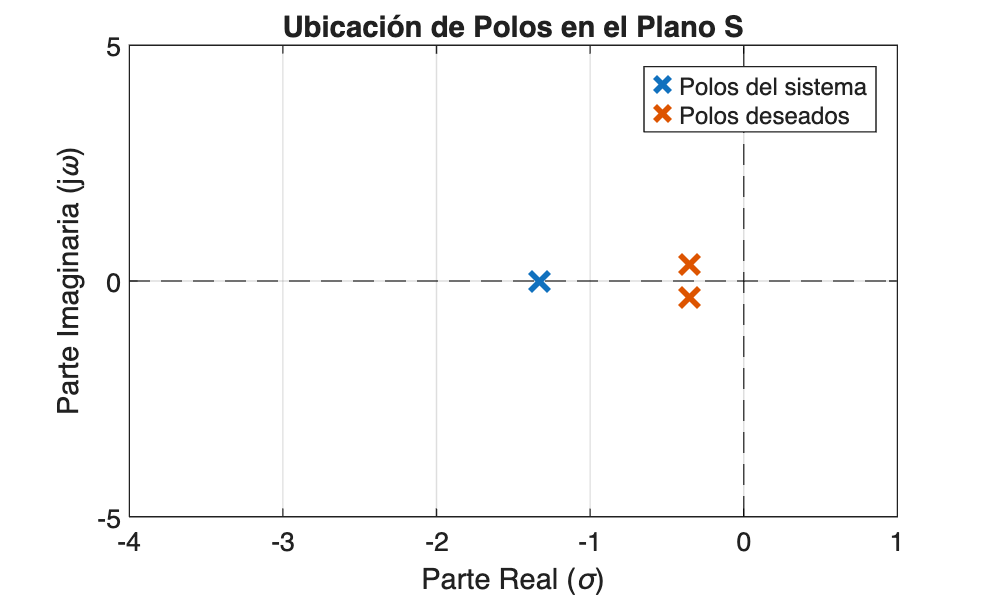



% Ver polos del sistema y polos que 
% buscamos ser dominantes

hold on
plot(real(poles_d), imag(poles_d), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)

xlim([-4 1])
ylim([-5 5])


grid on
xline(0, '--k') % Eje imaginario
yline(0, '--k') % Eje real

xlabel('Parte Real (\sigma)')
ylabel('Parte Imaginaria (j\omega)')
title('Ubicación de Polos en el Plano S')
legend('Polos del sistema', 'Polos deseados')
hold off


% Encontrar angulos de cada polo

% Calculamos el ángulo de cada polo respecto a sd
sd = poles_d(1);

angles = arrayfun(@(p) rad2deg(abs(angle(sd-p))), poles_r)

angles =        19.998
       168.01


angle_sum = sum(angles)

angle_sum =        188.01



syms phi

phi_angle = solve(angle_sum-phi == 180, phi);
vpa(phi_angle)

$$ans = 8.0066059932026973910978995263577$$



x_val = abs(imag(sd))/tand(phi_angle)

$$x\_val = \frac{\sqrt{51}}{20\,\tan\left(\frac{70426851108379\,\pi }{1583296743997440}\right)}$$


% Encontramos la alpha (cero) del sistema
beta = -(real(sd)-x_val);
vpa(beta)

$$ans = 2.8885714285714246000085313008931$$


% Usamos la condicón de magnitud para encontrar la ganancia
Gop_s_wKc = Gop_s/Kc

$$Gop\_s\_wKc = \frac{b+s}{10000\,s^{2}-17720}$$

Kc_den = subs(Gop_s_wKc, [b, s], [beta, sd])

$$Kc\_den = -\frac{-\frac{\sqrt{51}}{20\,\tan\left(\frac{70426851108379\,\pi }{1583296743997440}\right)}+\frac{\sqrt{51}\,\mathrm{i}}{20}}{10000\,{\left(\frac{7}{20}+\frac{\sqrt{51}\,\mathrm{i}}{20}\right)}^{2}-17720}$$

Kc = 1/abs(Kc_den)

$$Kc = \frac{20\,\sqrt{805051}}{\sqrt{\frac{51}{400\,{\tan\left(\frac{70426851108379\,\pi }{1583296743997440}\right)}^{2}}+\frac{51}{400}}}$$

Kc = vpa(Kc);

Kd = Kc

$$Kd = 7000.0000000000107385574688447645$$

Kp = vpa(Kc*beta)

$$Kp = 20220.000000000003219150007683515$$

simunlink_PID_creator('GEN__S3_2_PI', sym2tf(G_s), 1, 2022, 0, 700)


Modelo creado correctamente:
  GEN__S3_2_PI.slx


### Problema 3

clear all

syms Kc s a b

% Valores del ejercicio
G_s = 5/((s+2)*(s+1));
Gc_s = (Kc*(s+a)*(s+b)/s)

$$Gc\_s = \frac{\mathrm{Kc}\,\left(a+s\right)\,\left(b+s\right)}{s}$$


% Borrar
[nums, denms] = numden(Gc_s)

$$nums = \mathrm{Kc}\,\left(a+s\right)\,\left(b+s\right)$$

$$denms = s$$

expand(nums)

$$ans = \mathrm{Kc}\,s^{2}+\mathrm{Kc}\,a\,b+\mathrm{Kc}\,a\,s+\mathrm{Kc}\,b\,s$$


Gop_s = G_s*Gc_s

$$Gop\_s = \frac{5\,\mathrm{Kc}\,\left(a+s\right)\,\left(b+s\right)}{s\,\left(s+1\right)\,\left(s+2\right)}$$

Ts=2

Ts =      2


Mp = 0.10;

dampping = sqrt(log(Mp)^2/(pi^2 + log(Mp)^2))

dampping =       0.59116


Wn = 4/(dampping*Ts)

Wn =        3.3832



[N_Gop_s, D_Gop_s] = numden(Gop_s);
poles_r = solve(D_Gop_s == 0, s);
poles_r = double(poles_r)

poles_r =     -2
    -1
     0



N_Gop_s

$$N\_Gop\_s = 5\,\mathrm{Kc}\,\left(a+s\right)\,\left(b+s\right)$$


figure
plot(real(poles_r), imag(poles_r), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)


% Encontramos polinómio deseado
Pd_s = s^2 + (2*dampping*Wn*s) + Wn^2;
% Ver númericamente
var = vpa(Pd_s)

$$var = s^{2}+4.0\,s+11.446091339691033539338604896329$$


poles_d = vpa(solve(Pd_s == 0, s));
poles_d = double(poles_d)

poles_d =            -2 -     2.7288i
           -2 +     2.7288i


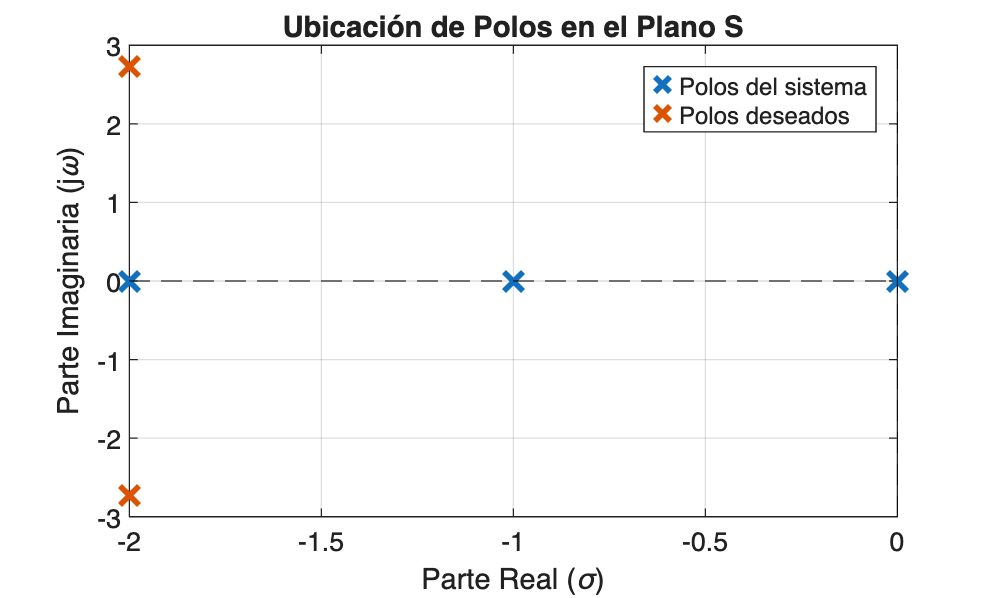



% Ver polos del sistema y polos que 
% buscamos ser dominantes

hold on
plot(real(poles_d), imag(poles_d), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)

grid on
xline(0, '--k') % Eje imaginario
yline(0, '--k') % Eje real

xlabel('Parte Real (\sigma)')
ylabel('Parte Imaginaria (j\omega)')
title('Ubicación de Polos en el Plano S')
legend('Polos del sistema', 'Polos deseados')
hold off


% Encontrar angulos de cada polo

% Calculamos el ángulo de cada polo respecto a sd
sd = poles_d(1);

angles = arrayfun(@(p) rad2deg(abs(angle(sd-p))), poles_r)

angles =            90
       110.13
       126.24


angle_sum = sum(angles)

angle_sum =        326.37



% Definimos un cero adicional
Z_b = -1/2;
% Encontrar ángulo desde sd de phi2
Z_b_angle = rad2deg(abs(angle(sd-Z_b)))

Z_b_angle =         118.8



angle_sum = angle_sum - Z_b_angle

angle_sum =        207.57



syms phi

phi_angle = solve(angle_sum-phi == 180, phi);
vpa(phi_angle)

$$ans = 27.567604578871510057069826871157$$



x_val = abs(imag(sd))/tand(phi_angle)

$$x\_val = \frac{3072302419377617}{1125899906842624\,\tan\left(\frac{80829071425067\,\pi }{527765581332480}\right)}$$


% Encontramos la alpha (cero) del sistema
alpha = -(real(sd)-x_val);
vpa(alpha)

$$ans = 7.2268182979953983426679934391728$$


% beta
beta = -Z_b;

% Usamos la condicón de magnitud para encontrar la ganancia
Gop_s_wKc = Gop_s/Kc

$$Gop\_s\_wKc = \frac{5\,\left(a+s\right)\,\left(b+s\right)}{s\,\left(s+1\right)\,\left(s+2\right)}$$

Kc_den = subs(Gop_s_wKc, [a, b, s], [alpha, beta, sd])

$$Kc\_den = \frac{-\frac{43612979339140137051380716492647235934536968244982747634860032}{31070061255161885862276068576230708557069255602547811101296909}-\frac{22768925314942340972937875926117700355109999923439349450932224}{31070061255161885862276068576230708557069255602547811101296909}\,\mathrm{i}}{\tan\left(\frac{80829071425067\,\pi }{527765581332480}\right)}-\frac{22768925314942340972937875926117700355109999923439349450932224}{31070061255161885862276068576230708557069255602547811101296909}+\frac{43612979339140137051380716492647235934536968244982747634860032}{31070061255161885862276068576230708557069255602547811101296909}\,\mathrm{i}$$

Kc = 1/abs(Kc_den)

$$Kc = \frac{1}{\sqrt{{\left(\frac{22768925314942340972937875926117700355109999923439349450932224}{31070061255161885862276068576230708557069255602547811101296909\,\tan\left(\frac{80829071425067\,\pi }{527765581332480}\right)}-\frac{43612979339140137051380716492647235934536968244982747634860032}{31070061255161885862276068576230708557069255602547811101296909}\right)}^{2}+{\left(\frac{43612979339140137051380716492647235934536968244982747634860032}{31070061255161885862276068576230708557069255602547811101296909\,\tan\left(\frac{80829071425067\,\pi }{527765581332480}\right)}+\frac{22768925314942340972937875926117700355109999923439349450932224}{31070061255161885862276068576230708557069255602547811101296909}\right)}^{2}}}$$

Kc = vpa(Kc)

$$Kc = 0.29226492435225023343684510850441$$


Kd = Kc

$$Kd = 0.29226492435225023343684510850441$$

Kp = vpa(Kc*(alpha + beta))

$$Kp = 2.2582779653472079981625523366466$$

Ki = vpa(Kc*alpha*beta)

$$Ki = 1.0560727515855414407220648911972$$

% simunlink_PID_creator('GEN__S3_3_PI', sym2tf(G_s), 1, 2.2582, 1.0560, 0.2922)
